# Step 8: 近似線形化

`get_sys` は、系統（または母線・機器・制御器）を運転点のまわりで線形化し、線形モデル E dx/dt = A x + B u、y = C x + D u を返します。値は運転点からの偏差です。線形化に Toolbox は要りません。

この Step は、GUILDA の基本的な流れの赤枠の部分です。

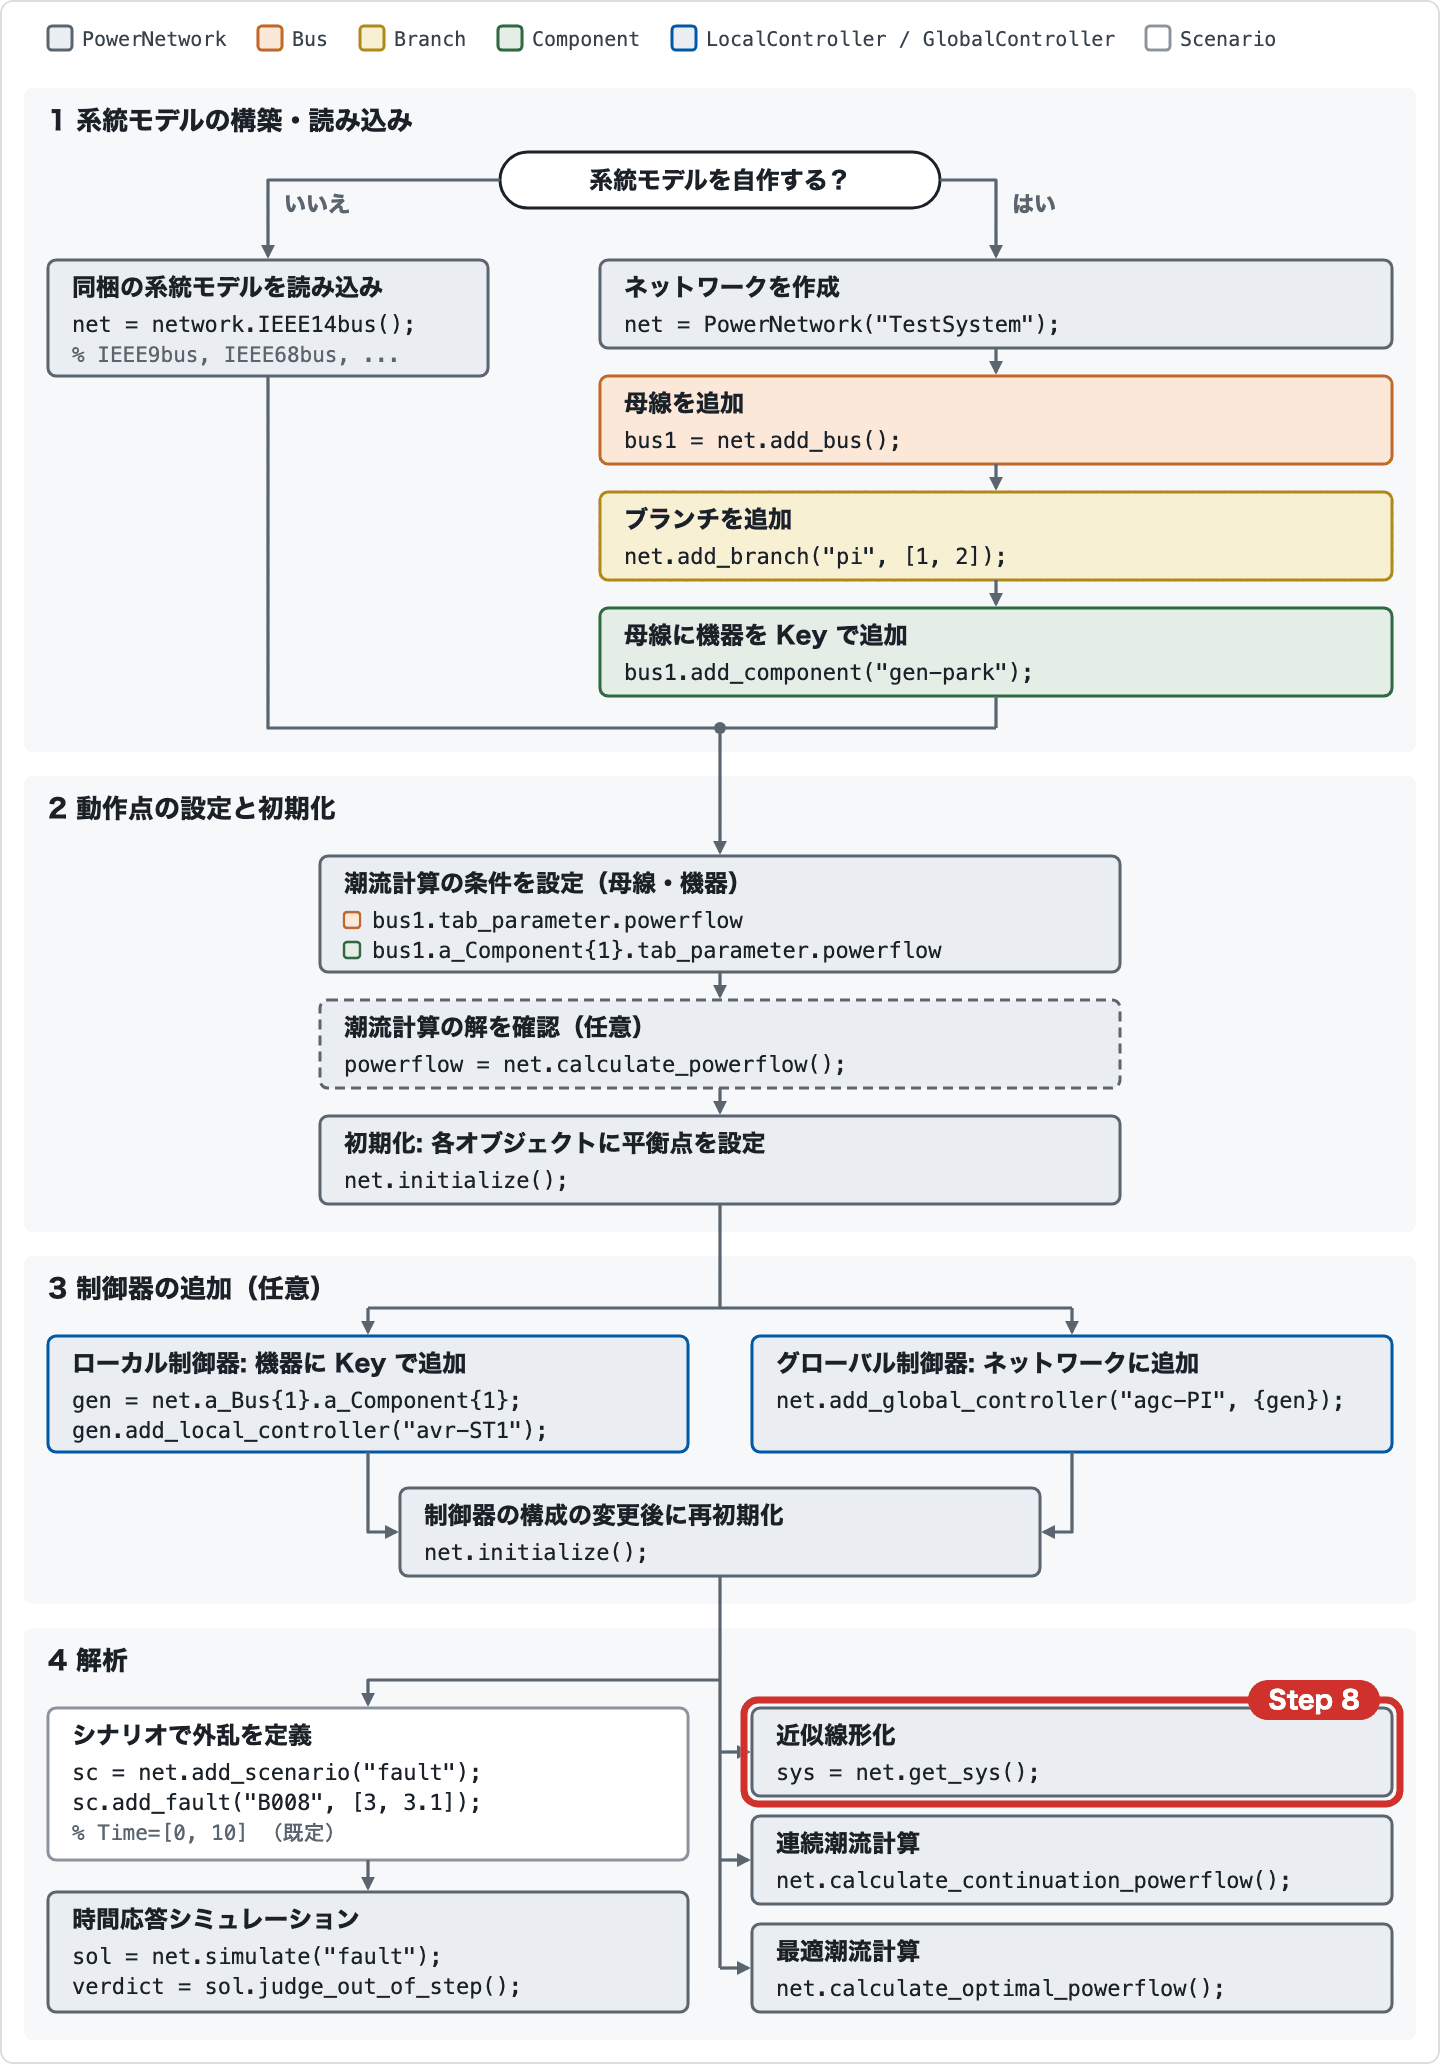

## この Step で分かること

- `get_sys` の呼び方と、結果 `ResultLIN` の中身（A〜E、状態・入力・出力の名前、変数の表）

- モデルの形 `Type`（`"ODE"` と `"DAE"`）と母線の表し方 `Port`

- 入力と出力の選び方（`Input`・`Output`）と、`get_ss` で受け取る形（`struct`・`ss`）

- 固有値の地図 `plot_eigenvalue`

- 部分系（機器・制御器・母線）の線形化と、要素ごとの寄与 `get_contribution`

- 制御器を加えた系統の線形化と、平衡点以外の点での線形化

各節は、線形化して結果を出すのに要るコードだけで進みます。**確かめる（省略できます）** の下のコードは、中身を見るためのものです。飛ばしても最後まで動きます。

## 1. 系統を線形化する: get_sys

同梱の IEEE 9 母線系統（AVR・PSS・ガバナ付きの発電機 3 台と負荷 3 つ）を読み込みます。`get_sys` を引数なしで呼ぶと、平衡点のまわりで系統全体を線形化します。

net = network.IEEE9bus(LocalController=true);
[res, flag, output] = net.get_sys();

出力は `[結果, flag, output]` です。`flag` は、行列がすべて有限で（`"ODE"` では）母線電圧を消去できたとき true です。`output` には線形化の情報があります。

**確かめる（省略できます）**

flag

flag = logical
   1


res

res =   ResultLIN のプロパティ:

    tab_variable: [72×8 table]
            rv_t: NaN
           Index: 1
        rv_point: [72×1 double]
          rm_Axx: [27×27 double]
          rm_Axv: [27×18 double]
           rm_Bx: [27×12 double]
          rm_Avx: [18×27 double]
          rm_Avv: [18×18 double]
           rm_Bv: [18×12 double]
            rm_E: [27×27 double]
            Type: "ODE"
               A: [27×27 double]
               B: [27×12 double]
               C: [27×27 double]
               D: [27×12 double]
               E: [27×27 double]
       StateName: [27×1 string]
       InputName: [12×1 string]
      OutputName: [27×1 string]
     sct_network: [1×1 struct]
            flag: 1
          output: [1×1 struct]
         options: [1×1 struct]
        s_solver: "SolverLIN"
       r_elapsed: 0.7618
       s_network: "PowerNetwork"
       l_success: 1


output

output = フィールドをもつ struct:
          s_issue: ""
        rcond_Avv: 0.0031
              n_x: 27
              n_v: 18
              n_u: 12
          message: "Linearized the network PowerNetwork at the equilibrium."
      sv_faultBus: [0×1 string]
    l_equilibrium: 1
          s_layer: "PowerNetwork"
          lv_flag: 1
         sv_issue: ""
       sv_message: "Linearized the network PowerNetwork at the equilibrium."
     rv_rcond_Avv: 0.0031
           result: [1×1 ResultLIN]


**注意:** 系統を編集した後に `get_sys` を呼ぶと、平衡点が古いので `GUILDA:PowerSystemModel:Stale` で止まります。先に `net.initialize()` を実行します。

## 2. ResultLIN の中身

`ResultLIN` の主なプロパティは次のとおりです。

状態は 27 個、入力は 12 個です。名前は「変数名_持ち主のタグ」です。`B001SG1` は母線 B001 の発電機、`B001SG1CA1` はその AVR、`B001SG1CP2` はその PSS です。変数の表には、状態 x、母線電圧 Vre・Vim、入力 u などが並び、`Equilibrium` 列が平衡点の値です。

**確かめる（省略できます）**

行列の大きさ、状態と入力の名前、変数の表の先頭を表示します。

[size(res.A); size(res.B); size(res.C); size(res.D); size(res.E)]

ans =     27    27
    27    12
    27    27
    27    12
    27    27


res.StateName(1:9)'

ans = 1×9 の string 配列
    "delta_B001SG1"    "omega_B001SG1"    "Eq_B001SG1"    "Vtr_B001SG1CA1"    "Vap_B001SG1CA1"    "Vst_B001SG1CA1"    "xiWS_B001SG1CP2"    "xi1_B001SG1CP2"    "xi2_B001SG1CP2"


res.InputName'

ans = 1×12 の string 配列
    "Pmech_B001SG1"    "Vfield_B001SG1"    "Pmech_B002SG1"    "Vfield_B002SG1"    "Pmech_B003SG1"    "Vfield_B003SG1"    "R_B005LRX1"    "X_B005LRX1"    "R_B006LRX1"    "X_B006LRX1"    "R_B008LRX1"    "X_B008LRX1"


head(res.tab_variable, 6)

    Index    Kind       Role          Owner         Name           Label           Bus      Equilibrium
    _____    ____    __________    ____________    _______    ________________    ______    ___________

      1      "x"     "variable"    "B001SG1"       "delta"    "delta_B001SG1"     "B001"      0.63655  
      2      "x"     "variable"    "B001SG1"       "omega"    "omega_B001SG1"     "B001"            0  
      3      "x"     "variable"    "B001SG1"       "Eq"       "Eq_B001SG1"        "B001"       1.0367  
      4      "x"     "variable"    "B001SG1CA1"    "Vtr"      "Vtr_B001SG1CA1"    "B001"         1.04  
      5      "x"     "variable"    "B001SG1CA1"    "Vap"      "Vap_B001SG1CA1"    "B001"       1.8069  
      6      "x"     "variable"    "B001SG1CA1"    "Vst"      "Vst_B001SG1CA1"    "B001"            0  



**注意:** 既定（`"ODE"`）では出力は状態そのもので（C は単位行列）、出力の名前は空です。E は単位行列とは限らないので、固有値は `eig(res.A, res.E)` で求めます。

## 3. モデルの形: Type と Port

`Type="ODE"`（既定）は母線電圧を消去したモデル、`Type="DAE"` は母線電圧を代数変数として残したモデルです。`"DAE"` では、母線ごとの変数と式が状態の後ろに並び、その行の E は 0 です。母線の表し方は `Port` で選びます。

`"DAE"` の形で、母線の変数を Vre・Vim にして線形化します。

resI = net.get_sys(Type="DAE", Port="I");

**確かめる（省略できます）**

`resI` の末尾の状態（母線の変数）を表示します。続けて、1 節の `res` の `Type` を設定して、同じ結果のまま形が切り替わることを確かめ、`"ODE"` に戻します。

resI.StateName(end-3:end)'

ans = 1×4 の string 配列
    "Vim6"    "Vim7"    "Vim8"    "Vim9"


res.Type = "DAE";
size(res.A)

ans =     45    45


res.StateName(end-5:end)'

ans = 1×6 の string 配列
    "rho4"    "rho5"    "rho6"    "rho7"    "rho8"    "rho9"


res.Type = "ODE";

**注意:** `Type` と `Port` の既定値は `GUILDA.setting` の ApproximateLinearization の項目で変えられます。有限の固有値は `"ODE"` と `"DAE"` で同じです。

## 4. 入力と出力を選ぶ: Input・Output・get_ss

`Input` と `Output` で、モデルの入力と出力を選びます。状態とその順番は変わりません。`Output` には次の種類と名前を混ぜて指定できます。

- `"x"`: すべての状態

- `"V"`: 各母線の電圧 Vre、Vim

- `"I"`: 各母線に機器が注入する電流 Ire、Iim

- `"y"`: 機器と制御器の出力

- 名前: 変数の表の `Label`（`"omega_B002SG1"` など）

出力を母線の電圧にします。

resV = net.get_sys(Output="V");

発電機 G1 の機械入力から 3 台の周波数偏差までのモデルを取り出します。

resP = net.get_sys(Input="Pmech_B001SG1", Output=["omega_B001SG1", "omega_B002SG1", "omega_B003SG1"]);

`get_ss` は、結果から別の形・入出力のモデルを取り出します。`Format="struct"` は行列と名前の構造体（Toolbox 不要）、`Format="ss"`（既定）は Control System Toolbox の記述子形式の `ss` オブジェクトです。

sct = res.get_ss("ODE", Output="V", Format="struct");
sys = res.get_ss("ODE", Input="Pmech_B001SG1", Output=["omega_B001SG1", "omega_B002SG1", "omega_B003SG1"]);

`ss` オブジェクトには、Control System Toolbox の関数がそのまま使えます。G1 の機械入力を 0.01 pu ステップ状に上げたときの周波数偏差の応答です。

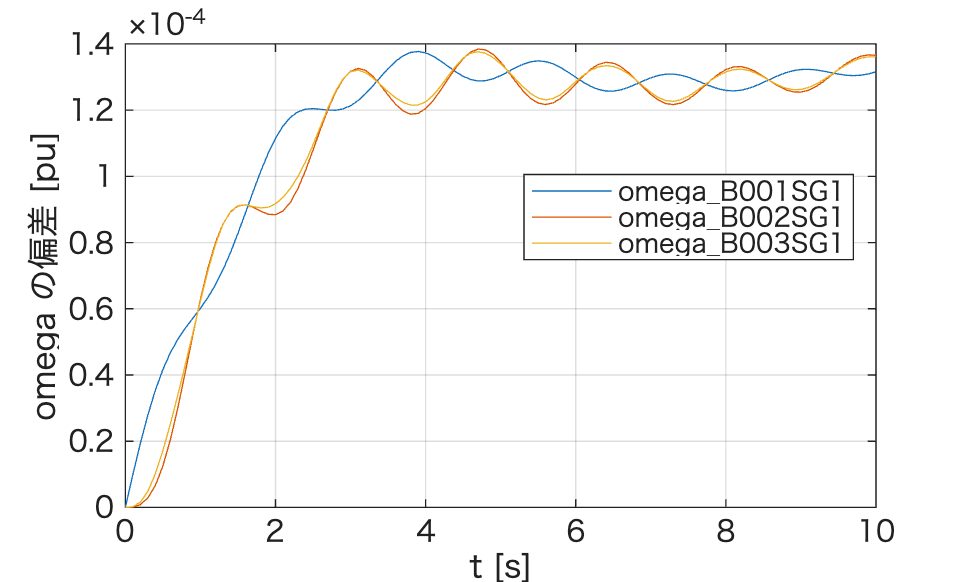

[y, t] = step(0.01 * sys, 10);
figure
plot(t, squeeze(y))
legend(sys.OutputName, Interpreter="none", Location="best")
xlabel("t [s]"); ylabel("omega の偏差 [pu]"); grid on

**確かめる（省略できます）**

選んだ出力と入力の名前、構造体のフィールド、`ss` のクラスを表示します。

size(resV.C)

ans =     18    27


resV.OutputName(1:4)'

ans = 1×4 の string 配列
    "Vre_B001"    "Vim_B001"    "Vre_B002"    "Vim_B002"


resP.InputName, resP.OutputName

ans = "Pmech_B001SG1"

ans = 3×1 の string 配列
    "omega_B001SG1"
    "omega_B002SG1"
    "omega_B003SG1"


fieldnames(sct)'

ans = 1×8 の cell 配列
    {'A'}    {'B'}    {'C'}    {'D'}    {'E'}    {'StateName'}    {'InputName'}    {'OutputName'}


class(sys)

ans = 'ss'

**注意:** `get_sys` の `Format` に `"struct"` や `"ss"` を指定すると、`ResultLIN` の代わりにその形で直接受け取れます。`get_sys`・`get_ss` のその他のオプションは、リファレンスで確かめられます: [get_sys のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=PowerSystemModel&method=get_sys')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）・[get_ss のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultLIN&method=get_ss')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 5. 固有値を描く: plot_eigenvalue

`plot_eigenvalue` は、有限の固有値を複素平面に描きます。実部が正（`Tolerance` より大きい）の固有値は赤で描きます。

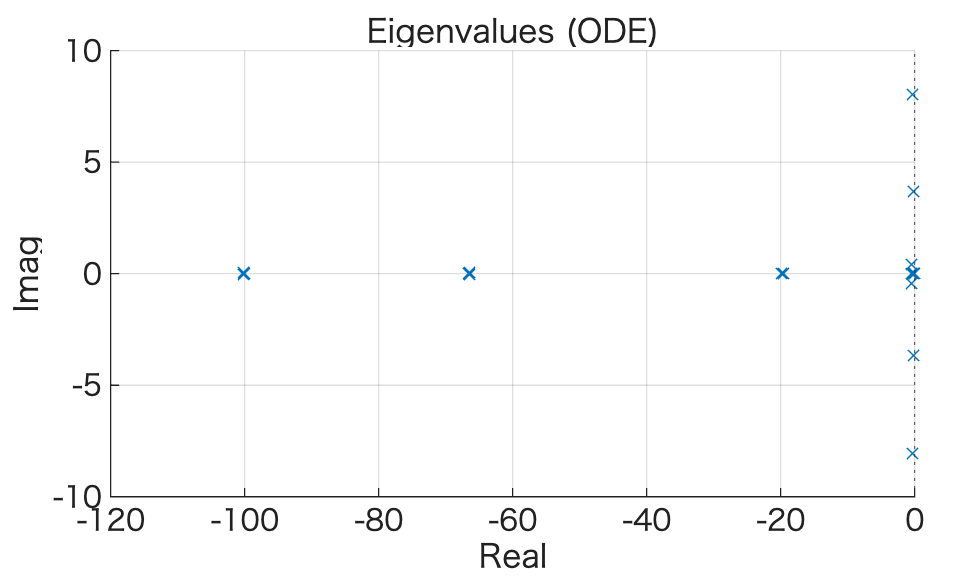

G = res.plot_eigenvalue();

結果の図は `GraphChart` で、要素は `"stable"` と `"unstable"` です（Step 7 と同じく `set_style` などが使えます）。数値で見るには `get_mode` を使います（7 節でも使います）。

sct_mode = res.get_mode();

tab_mode = 16×4 table
         Eigenvalue          Frequency    DampingRatio       Owner    
    _____________________    _________    ____________    ____________

    -2.9315e-13+0i                   0           NaN      "B002SG1"   
     -0.0069046+0i                   0           NaN      "B002SG1CP2"
       -0.10078+0i                   0           NaN      "B001SG1CP2"
       -0.10217+0i                   0           NaN      "B003SG1CP2"
       -0.15023+3.6739i        0.58471      0.040858      "B002SG1"   
        -0.1716+0i                   0           NaN      "B003SG1"   
       -0.32656+8.0476i         1.2808      0.040546      "B003SG1"   
       -0.48189+0i                   0           NaN      "B001SG1"   
       -0.52661+0.41808i       0.06654       0.78319      "B001SG1"   
        -19.617+0i                   0           NaN      "B001SG1CA1"
        -19.909+0i                   0           NaN      "B001SG1CA1"
         -19.93+0i                   0           NaN  

tab_mode = sct_mode.tab_mode

`get_mode` は 1 行が 1 つのモード（複素共役の組は虚部が正のほう）で、固有値 `Eigenvalue`、周波数 `Frequency` [Hz]、ダンピング比 `DampingRatio`、いちばん大きく参加している持ち主 `Owner` です。実部の大きい（安定の余裕が小さい）順に並びます。先頭の 0 に近い固有値（基準の位相に当たるもの）を除くと、実部はすべて負なので、この運転点は小信号安定です。

**確かめる（省略できます）**

振動モードだけを見るには、`MinFrequency` で周波数の下限を指定します。

res.get_mode(MinFrequency=0.1)

ans = 2×4 table
       Eigenvalue       Frequency    DampingRatio      Owner  
    ________________    _________    ____________    _________

    -0.15023+3.6739i     0.58471       0.040858      "B002SG1"
    -0.32656+8.0476i      1.2808       0.040546      "B003SG1"


**注意:** `get_mode` の結果の構造体 `sct_mode` には、表 `sct_mode.tab_mode` のほかに、参加係数 `sct_mode.rm_participation` とモード形 `sct_mode.cm_shape` があります。その他のオプションは、`get_mode` のリファレンスで確かめられます: [その他のオプションはこちら](matlab:writelines("<script>location.replace('file://"+replace(fullfile(GUILDA.pwd,"_GUILDAdoc","method.html"),filesep,"/")+"#class=ResultLIN&method=get_mode')</script>",fullfile(tempdir,"guilda_doc.html"));web(fullfile(tempdir,"guilda_doc.html"),"-browser"))（ブラウザで開きます）

## 6. 部分系の線形化

`get_sys` は系統だけでなく、母線・機器・ローカル制御器・グローバル制御器にもあります。部分系のモデルは、母線電圧（と入力）を入力、電流（と出力）を出力とするポートのモデルです。

gen = net.get_element("B001SG1");     % 母線 B001 の発電機
resG = gen.get_sys();

機器の `get_sys` は、その機器のローカル制御器（AVR、PSS、ガバナ）を含みます。制御器だけを線形化することもできます。発電機の制御器は `gen.avr`、`gen.pss`、`gen.governor` で取り出せます。

avr = gen.avr;
resC = avr.get_sys();

**確かめる（省略できます）**

発電機と AVR のモデルの状態・入力・出力の名前を表示します。

resG.StateName'

ans = 1×9 の string 配列
    "delta_B001SG1"    "omega_B001SG1"    "Eq_B001SG1"    "Vtr_B001SG1CA1"    "Vap_B001SG1CA1"    "Vst_B001SG1CA1"    "xiWS_B001SG1CP2"    "xi1_B001SG1CP2"    "xi2_B001SG1CP2"


resG.InputName'

ans = 1×9 の string 配列
    "Vre_B001"    "Vim_B001"    "Pmech_B001SG1"    "Vfield_B001SG1"    "Vref_B001SG1CA1"    "Vpss_B001SG1CA1"    "Ifield_B001SG1CA1"    "omega_B001SG1CP2"    "Pmech_ref_B001SG1CG1"


resG.OutputName'

ans = 1×7 の string 配列
    "Ire_B001SG1"    "Iim_B001SG1"    "Y_omega_B001SG1"    "Ifield_B001SG1"    "Vfield_B001SG1CA1"    "Vpss_B001SG1CP2"    "Pmech_B001SG1CG1"


resC.StateName'

ans = 1×3 の string 配列
    "Vtr_B001SG1CA1"    "Vap_B001SG1CA1"    "Vst_B001SG1CA1"


resC.InputName'

ans = 1×5 の string 配列
    "Vre_B001"    "Vim_B001"    "Vref_B001SG1CA1"    "Vpss_B001SG1CA1"    "Ifield_B001SG1CA1"


resC.OutputName'

ans = "Vfield_B001SG1CA1"

**注意:** 母線の `get_sys`（`net.get_element("B005").get_sys()` など）は、その母線の機器をまとめたモデルです。ブランチには線形モデルがありません。

### 要素ごとの寄与: get_contribution

`get_contribution` は、`"DAE"` の行列のうち、指定した要素（タグ、クラス名、パッケージ名）が受け持つ部分を、線形化の結果（ResultLIN）として返します。この結果はすべての断面を持ち、A などはその要素の部分だけです（Type は "DAE" だけです）。部分の値なので、系統全体の固有値などの意味はありません。2 つ目の出力は、断面ごとの、その要素が変える成分の位置です。AVR が受け持つ A の成分を描きます。

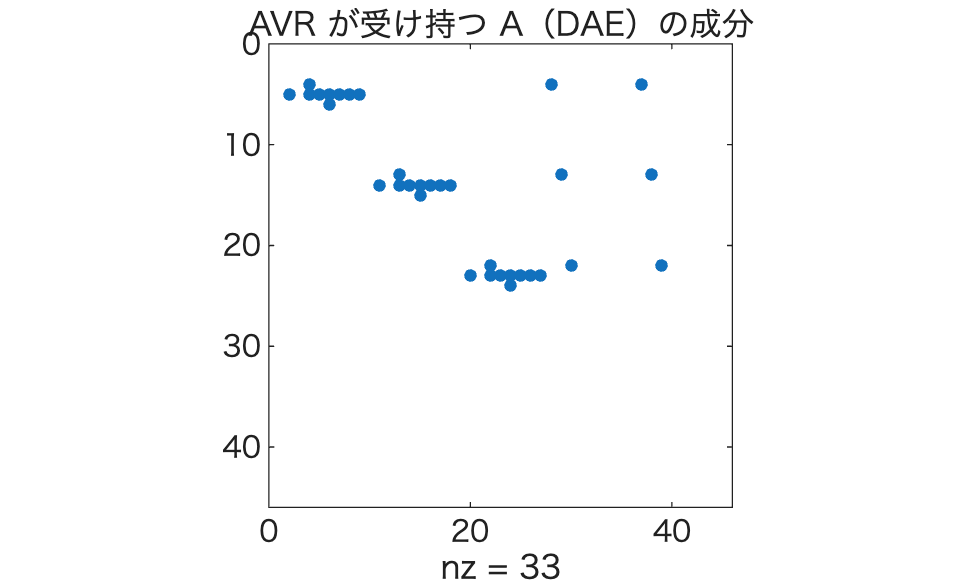

[res_avr, msk_avr] = res.get_contribution("controller.avr");
figure
spy(msk_avr(res_avr.Index).A)
title("AVR が受け持つ A（DAE）の成分")

すべての要素の寄与を足すと、`"DAE"` の行列になります。タグ（`"B001SG1"`）やクラス（`"LocalController"`、`"Branch"`）も指定できます。

## 7. 制御器を加えた系統の線形化

系統に加えた制御器は、線形モデルに含まれます（制御器の加え方は Step 2）。ここでは、周波数を戻すグローバル制御器を加えます。まず種類を確かめてみましょう。

GUILDA.dictionary("GlobalController");

 
Search for 'GlobalController' class
  Link   Type        Key     class tree
  [doc]  -:Abstract          GlobalController
  [doc]  o:Concrete  agc-PI    ┗━━ controller.agc.broadcast_PI_AGC


今回は PI 制御の AGC（`agc-PI`）を使います。発電機 G1 と G2 に加え、平衡点を求め直してから線形化します。

net.add_global_controller("agc-PI", ["B001SG1", "B002SG1"]);

INFO: The global controller 'PowerNetworkAGC1' is connected: Pmech_B001SG1_PowerNetworkAGC1 -> Pmech_B001SG1; Pmech_B002SG1_PowerNetworkAGC1 -> Pmech_B002SG1.


net.initialize();
resAGC = net.get_sys();

AGC の有無で固有値を比べます。

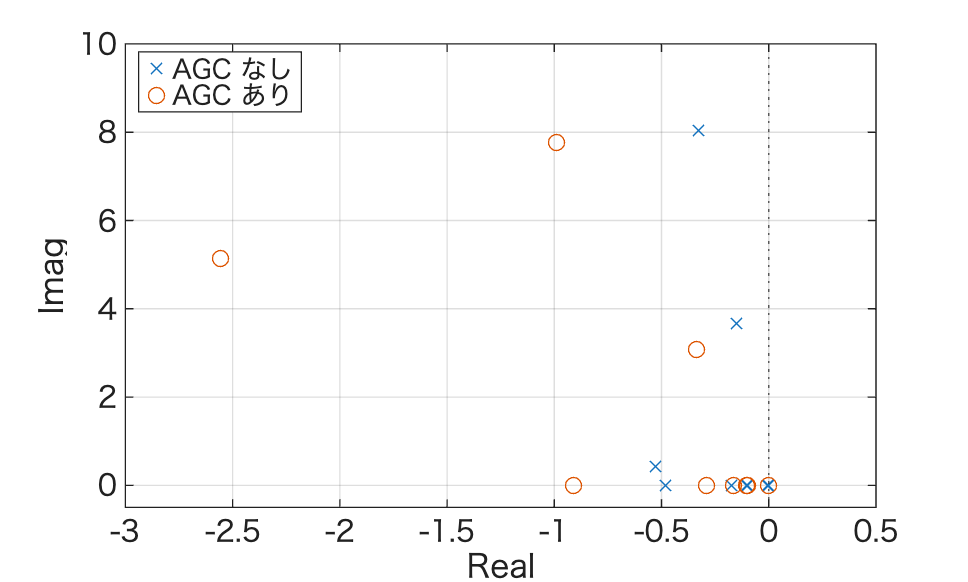

modeAGC = resAGC.get_mode().tab_mode;
figure
plot(real(tab_mode.Eigenvalue), imag(tab_mode.Eigenvalue), "x", real(modeAGC.Eigenvalue), imag(modeAGC.Eigenvalue), "o")
xline(0, ":")
xlim([-3 0.5]); ylim([-0.5 10])
legend(["AGC なし", "AGC あり"], Location="best")
xlabel("Real"); ylabel("Imag"); grid on

**確かめる（省略できます）**

グローバル制御器の状態は先頭に並びます（ここでは AGC の積分器 1 個が増えて 28 個）。

size(resAGC.A)

ans =     28    28


resAGC.StateName(1:3)'

ans = 1×3 の string 配列
    "xi_PowerNetworkAGC1"    "delta_B001SG1"    "omega_B001SG1"


**注意:** 制御器を加えたり削除したりした後は `net.initialize()` が必要です。グローバル制御器だけを `con.get_sys()` で線形化することもできます。

## 8. 平衡点以外の点で線形化する

`get_sys` の 1 つ目の引数で、線形化する点を与えます。

- `[]`（既定）: `net.initialize` で求めた平衡点

- `{sim, t}`: シミュレーション結果 `sim` の時刻 t の状態（`{sim, t, "before"}` で、その時刻の切り替えの直前）

- ベクトル: `net.get_variable_map()` の先頭の行（x、Vre、Vim、u、uc）の順の値

地絡の後の 2 秒の状態で線形化します（シナリオの作り方は Step 5）。

sc = net.add_scenario("fault");
sc.add_fault("B007", [1, 1.05]);
sim = net.simulate("fault", Time=[0, 3]);
resT = net.get_sys({sim, 2});

**確かめる（省略できます）**

線形化した点が平衡点かどうかと、そのメッセージを表示します。

resT.output.l_equilibrium

ans = logical
   0


resT.output.message

ans = "Linearized the network PowerNetwork at the given point."

**注意:** 平衡点でない点では、状態の微分が 0 でないので、線形モデルは「その点での接線」です。`output.l_equilibrium` が false になり、`plot_eigenvalue` の題にも「at the given point」が付きます。

## 次の Step

- 次は Step 9: 最適潮流計算です。

- 固有値、ダンピング比、参加係数から系統の揺れを読む方法は Part 5: 近似線形化で学びます。

[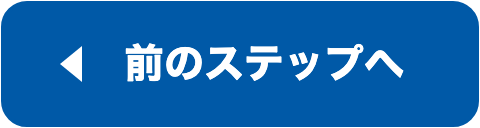](matlab:open('Step7_Visualization.mlx'))　　[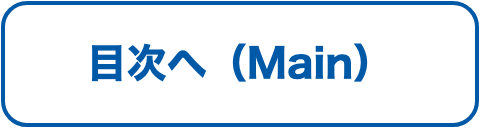](matlab:open('Main.mlx'))　　[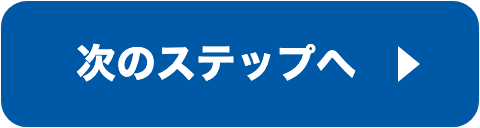](matlab:open('Step9_OptimalPowerFlow.mlx'))